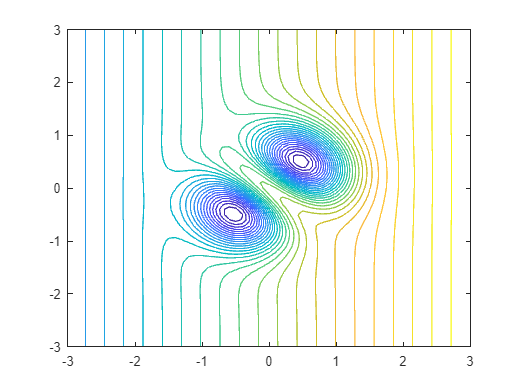

clear all
close all
syms x1 x2
f = x1-(4*(x1+x2).*exp(-x1.^2 - x2.^2)+0.1)^2;
f_num = matlabFunction(f);

figure;
[X, Y] = meshgrid(-3:0.1:3, -3:0.1:3);
Z = f_num(X, Y);
contour(X, Y, Z, 30);


P01=[1, 0.5];
P02=[-1.8, -1.5];
eps = 1e-3;
Nmax = 1000;

[x, i, x_vec] = max_fall(f, P01, eps, Nmax)

x =     0.4698    0.5103


i = 7

x_vec =     0.5307    0.3952
    0.5057    0.5060
    0.4754    0.4992
    0.4729    0.5099
    0.4700    0.5092
    0.4698    0.5103


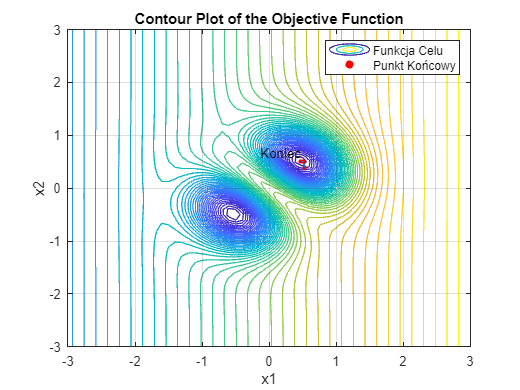

plot_result(f_num, x, x_vec)

[x, i, x_vec] = max_fall(f, P02, eps, Nmax)

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: -322094824551023623631011840.000000 



x = 1.0e+26 *

   -3.2209   -0.0424


i = 3

x_vec = 1.0e+26 *

   -3.2209   -0.0424
   -3.2209   -0.0424


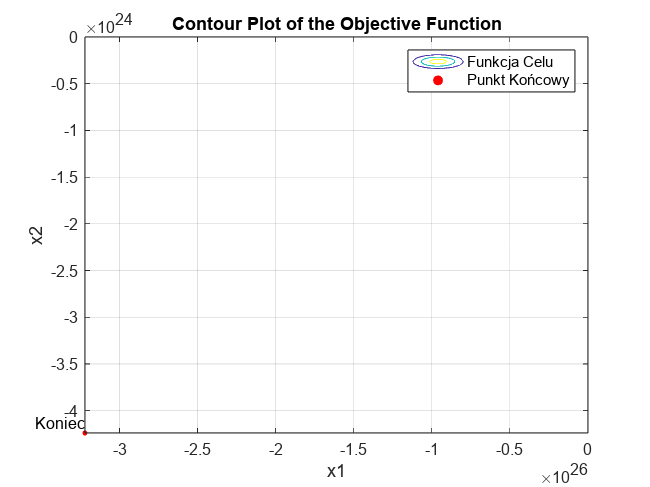

plot_result(f_num, x, x_vec)

[x, i, x_vec] = newton_fall(f, P01, eps, Nmax)

x =     0.4694    0.5103


i = 4

x_vec =     0.4915    0.4576
    0.4693    0.5103
    0.4694    0.5103


plot_result(f_num, x, x_vec)
[x, i, x_vec] = newton_fall(f, P02, eps, Nmax)

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: -19724805477198876895151652864.000000 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: NaN 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: NaN 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: NaN 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: NaN 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: NaN 

 
Exiting: Maximum number of function evaluations has been exceeded
         - incre

x =    NaN   NaN


i = 1001

x_vec = 1.0e+28 *

   -1.9725    1.0080
       NaN       NaN
       NaN       NaN
       NaN       NaN
       NaN       NaN
       NaN       NaN
       NaN       NaN
       NaN       NaN
       NaN       NaN
       NaN       NaN


plot_result(f_num, x, x_vec)

Kolos

f= 0.3*x1+0.1*x2+(-3.5+0.5*x1.^2+0.5*x2.^2).^2+100*x1 .* exp(-x1.^2 - x2.^2)

$$f = \frac{3\,x_{1}}{10}+\frac{x_{2}}{10}+100\,x_{1}\,{\mathrm{e}}^{-{x_{1}}^{2}-{x_{2}}^{2}}+{\left(\frac{{x_{1}}^{2}}{2}+\frac{{x_{2}}^{2}}{2}-\frac{7}{2}\right)}^{2}$$

f_num = matlabFunction(f);
eps = 1e-6;
P01=[1.5, -0.5];
[x, i, x_vec] = max_fall(f, P01, eps, Nmax)

x =    -2.4540   -0.5025


i = 142

x_vec =     2.5268   -0.9280
    2.2790   -1.5510
    2.2106   -1.5238
    2.1311   -1.7230
    2.0737   -1.7002
    2.0160   -1.8442
    1.9628   -1.8229
    1.9159   -1.9400
    1.8646   -1.9194
    1.8243   -2.0204


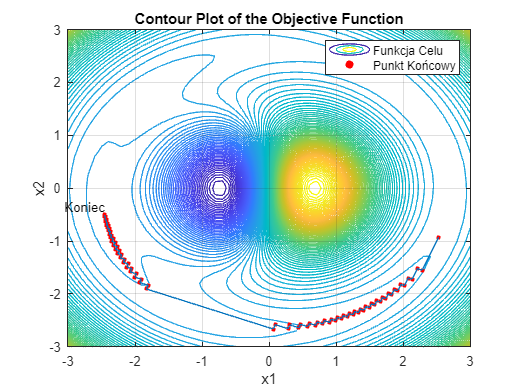

plot_result(f_num, x, x_vec)

f= 0.3*x1+0.1*x2+(-3.5+0.5*x1.^2+0.5*x2.^2).^2+100*x1 .* exp(-x1.^2 - x2.^2);
f_num = matlabFunction(f);
eps = 1e-6;
P01=[1.5, -0.5];
[x, i, x_vec] = newton_fall(f, P01, eps, Nmax)

x =    -2.4540   -0.5025


i = 13

x_vec =     2.4954   -1.0107
    2.2602   -1.5797
    1.7736   -2.1498
    0.8634   -2.6475
   -0.2074   -2.7641
   -1.2670   -2.4295
   -2.0757   -1.7043
   -2.4635   -0.8133
   -2.4454   -0.5206
   -2.4540   -0.5027


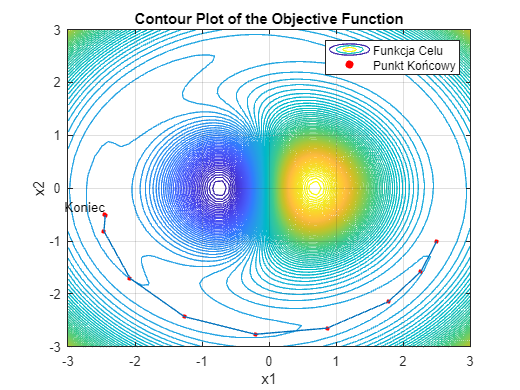

plot_result(f_num, x, x_vec)

function [x, i, x_vec] = max_fall(f, x0, eps, Nmax)
i = 1;
x_vec = [x0];
x = x0;
x_prev = x0;
syms x1 x2
grad = gradient(f, [x1, x2]).';
f_num = matlabFunction(f);

while i <= Nmax
    x_prev = x;
    d = -double(subs(grad, [x1, x2], [x(1), x(2)]));
    f_l = @(h) f_num(x(1) + h*d(1), x(2) + h*d(2));
    h = fminsearch(f_l, 0);
    x = x_prev + h*d;
    x_vec(i, :) = x;
    i = i + 1;
    if rms(x_prev - x) <= eps
        return;
    end %if
end %while
end %function

function [x, i, x_vec] = newton_fall(f, x0, eps, Nmax)
i = 1;
x_vec = [x0];
x = x0;
x_prev = x0;
syms x1 x2
grad = gradient(f, [x1, x2]).';
hesjan = hessian(f, [x1, x2]);
inv_hesjan = inv(hesjan);
f_num = matlabFunction(f);

while i <= Nmax
    x_prev = x;
    f_n = -inv_hesjan*grad.';
    d = -double(subs(f_n, [x1, x2], [x(1), x(2)]));
    f_l = @(h) f_num(x(1) + h*d(1), x(2) + h*d(2));
    h = fminsearch(f_l, 0);
    x = x_prev + h*d.';
    x_vec(i, :) = x;
    i = i + 1;
    if rms(x_prev - x) <= eps
        return;
    end %if
end %while
end %function

function [] = plot_result(f, x, x_vec)
figure;
[X, Y] = meshgrid(-3:0.1:3, -3:0.1:3);
Z = f(X, Y);
contour(X, Y, Z, 100);
title('Contour Plot of the Objective Function');
xlabel('x1');
ylabel('x2');
hold on;

scatter(x_vec(:, 1), x_vec(:, 2), 10, 'r', 'filled');
hold on; % to keep the scatter plot
line(x_vec(:, 1), x_vec(:, 2));
hold off;
text(x(1), x(2), '  Koniec', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');

legend('Funkcja Celu', 'Punkt Końcowy');
grid on;
hold off;

end